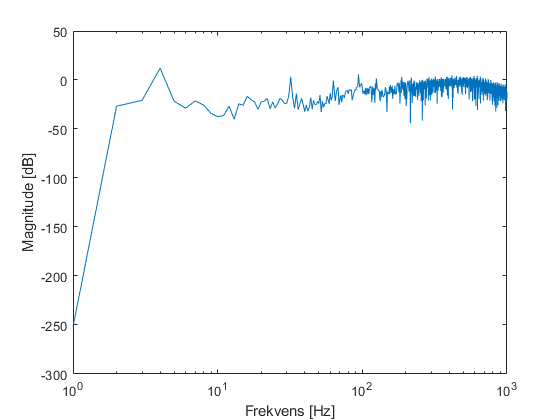

clear;
close all;
clc;

load('ECG_noisy_signal.mat');

s = signal_QRS;
fs = f_sample;

% Remove DC:
dc = mean(s);
s = s - dc;

% Studér EKG og dokumentér nytte-frekvensområde (båndbredde)

% Varighed af signal
N = length(s);
Tlength = N*1/fs;

S = fft(s);

% Frekvens akse:
delta_f = fs/N;
f_axis = 0:delta_f:fs-delta_f;

logX = (20*log10(abs((1/N)*S(1:0.5*fs))));

% ***** Plots ***************************************************
figure(1); clf
semilogx(logX);
xlabel('Frekvens [Hz]');
ylabel('Magnitude [dB]');

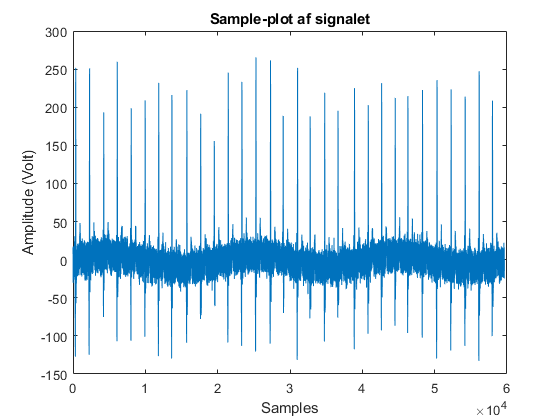


figure(2)
plot(s)
xlabel('Samples')
ylabel('Amplitude (Volt)')
title('Sample-plot af signalet')

% Her ser vi blot signalet tegnet direkte.

load lp_filter.m;

Error using load
Number of columns on line 11 of ASCII file lp_filter.m must be the same as previous lines.